# Simulación de Monte-Carlo

Una simulación de Monte-Carlo utiliza simulaciones que evolucionan aleatoriamente.

El concepto es, a partir de una muestra lo suficientemente grande de una población, obtener el valor esperado.

Para ejemplificar este ejemplo, vamos a simular el siguiente caso:

Se tiene una mesa con dos contenedores en ella:

- Uno cuadrado de área: $A_{\mathrm{cuadrado}} =\mathrm{a²}$

- Uno circular, de área: $A_{\textrm{círculo}} =\pi \cdot \textrm{a²}$

Queremos estimar el valor de $\pi \;$, el cual se puede obtener al dividir ambas áreas: $\pi =\frac{\;A_{\textrm{círculo}} }{A_{\textrm{cuadrado}} }$.

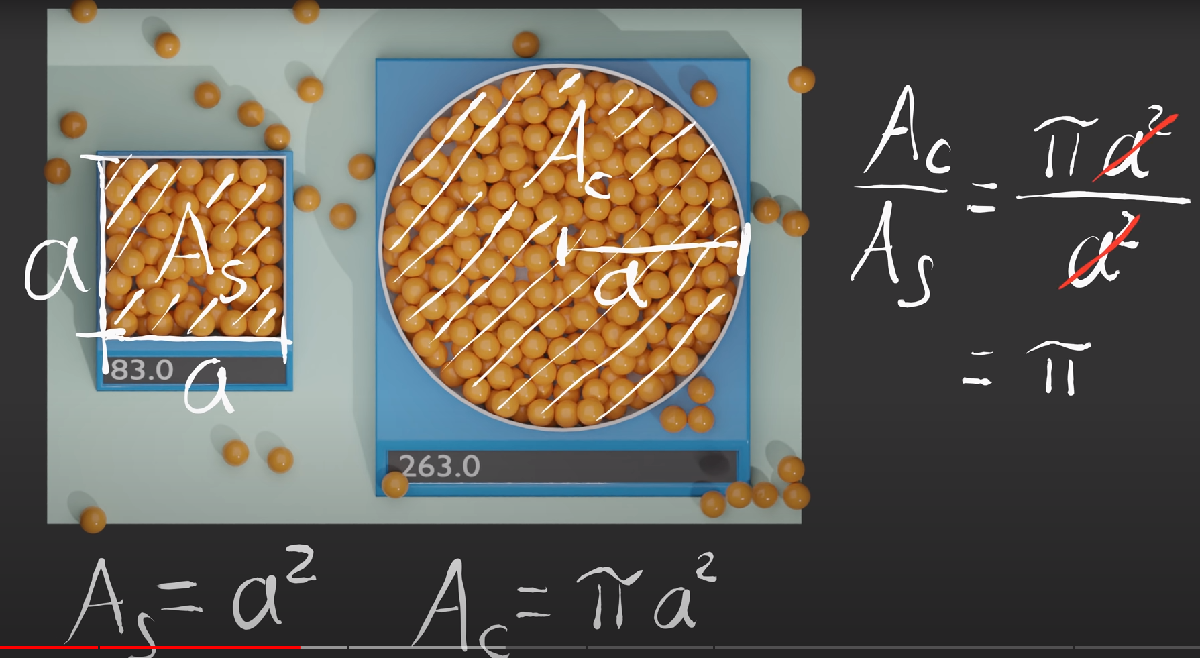

La simulación va a consisitir de dejar caer una pelotita en cualquier parte de la mesa, ya sea en el contenedor circular, cuadrado, o fuera de ellos. Vamos a contar la cantidad de pelotas en cada contenedor, y obtener el valor de $\pi \;$en función de la cantidad de muestras.

## Draw containers and table

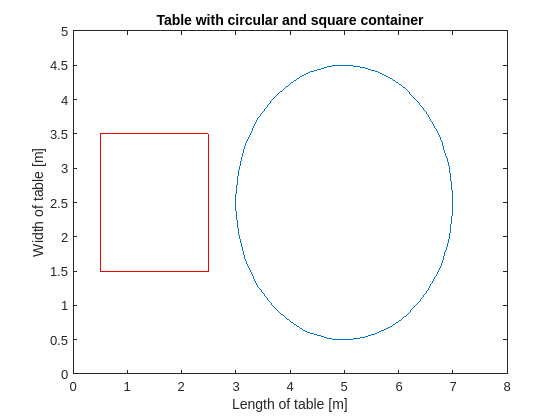

clc; clear; close all;
table_size_x = 8; table_size_y = 5; % Table length and width

% Draw circular container
xc = 5; yc = 2.5;   % Center of the circle
r = 2;              % Radius of the circle
theta = linspace(0,2*pi);
x = r*cos(theta) + xc;
y = r*sin(theta) + yc;

figure(1);
plot(x, y);
axis([0, table_size_x, 0, table_size_y]);
hold on;

% Draw square container
vertice_x = 0.5;
vertice_y = 1.5;
plot([vertice_x vertice_x+r],[vertice_y, vertice_y], "Color","r")
plot([vertice_x, vertice_x+r], [vertice_y+r, vertice_y+r], "Color", "r");
plot([vertice_x, vertice_x], [vertice_y, vertice_y+r], "Color", "r");
plot([vertice_x+r, vertice_x+r], [vertice_y, vertice_y+r], "Color", "r")

xlabel("Length of table [m]");
ylabel("Width of table [m]");
title("Table with circular and square container");

## Generate points, and calculate where they fall

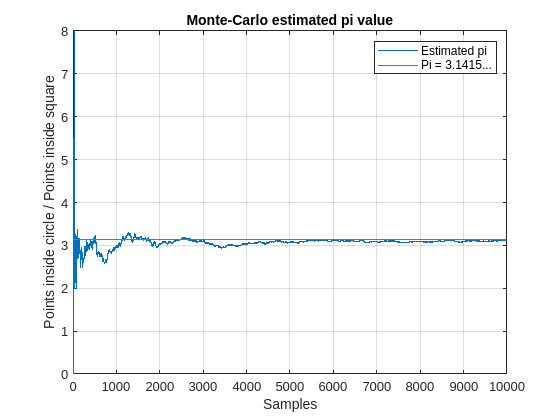

samples = 10000;     % Amount of samples of the experiment

points = table_size_x*rand([samples, 1]);
points(:,2) = table_size_y*rand([samples, 1]);
points_in_square = 0;
points_in_circle = 0;
points_outside = 0;
pi_data = zeros(1, samples);

for i=1:samples
    if(is_inside_circle(points(i,1), points(i,2), xc, yc, r))
        points_in_circle = points_in_circle + 1;
    elseif(is_inside_square(points(i,1), points(i,2), vertice_x, vertice_y, r))
        points_in_square = points_in_square + 1;
    else
        points_outside = points_outside + 1;
    end

    if (points_in_square > 0)
        pi_data(i) = points_in_circle / points_in_square;
    else
        pi_data(i) = 0;
    end
end

figure(2);
grid on;
plot(1:1:samples, pi_data);
hold on;
plot([1, samples], [pi, pi]);
legend("Estimated pi", "Pi = 3.1415...");
xlabel("Samples");
ylabel("Points inside circle / Points inside square");
title("Monte-Carlo estimated pi value")
grid on;